# MIT 2.12 Introduction to Robotics

## Virtual Lab 11 - Robot Manipulation and Trajectory Planning with Matlab

## Task 1. Joint Space and Task Space Trajectory Control

## April 2020

## 0. Initial Setup

In this example, we will use the KINOVA Gen3 Manipulator that comes with the Robotic System Toolbox. We will plan the trajectory in both joint space and task space. And control the manipulator to follow those trajectories in closed-loop.

% First, load the robot. Matlab takes in robots models in Rigid Body Tree form (RBT)
% that defines the kinmeatics of the robot configuration. In the pre-defined RBT model,
% the robot is defined with its base, joints, links and actuators. You can find
% RBT information here: https://www.mathworks.com/help/robotics/ref/rigidbodytree.html
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);

% Obtain default configuration
currentRobotJConfig = homeConfiguration(robot);

% Extract information from the RBT model
numJoints = numel(currentRobotJConfig);
endEffector = "EndEffector_Link";

% Specify the trajectory time step and approximate desired tool speed
timeStep = 0.1; % seconds
toolSpeed = 0.1; % m/s

% Set the initial and final end-effector pose.
jointInit = currentRobotJConfig;
taskInit = getTransform(robot,jointInit,endEffector);

**Question****:** What is the following line trying to accomplish?  Please be specific on the use of trvec2tform and axang2tform.

taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]);

## 1.a Task space trajectory generation

% Define trajectory times based on traveling distance and desired tool speed
distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));
initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];

% Generate waypints and velocities at waypoints
[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes);

## 1.b Follow the task space trajectory

tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'EndEffectorName','EndEffector_Link');

**Question**: What is the following line trying to accomplish? Please be specific: what is the shape of tsMotionModel.Kp and .Kd Why do we set these values to zero? 

tsMotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;

% Set initial condition
q0 = currentRobotJConfig; 
qd0 = zeros(size(q0));

The following line inputs system dynamics and solves the ODE.

**Question**: What does exampleHelperTimeBasedTaskInputs() do? Why is it put in this way in ode15s?

[tTask,stateTask] = ode15s(@(t,state) exampleHelperTimeBasedTaskInputs(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0; qd0]);

## 1.c Visualize the result

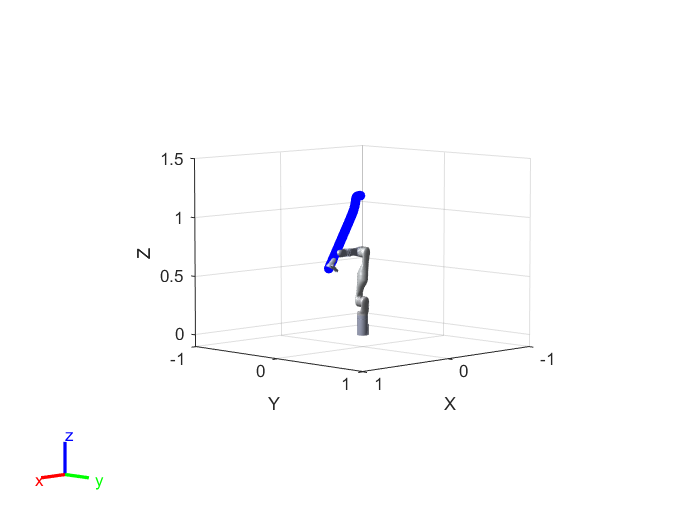

figure
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tTask,stateTask(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',20)
    drawnow;
end

**TO DO****: **Plot the Waypoints trajectories for part 1.a and 1.b in the same plot. Save and include in the deliverable. Comment on the end-effector trajectory and the planned trajectory.

## 2.a Joint space trajectory generation

% Set up the inverseKinematics Class
ik = inverseKinematics('RigidBodyTree',robot);
% Set up solver parameter
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

% Compute the final joint configurations 
initialGuess = wrapToPi(jointInit);
jointFinal = ik(endEffector,taskFinal,weights,initialGuess);
jointFinal = wrapToPi(jointFinal);

**Question**: What is the shape of jointConfigArray? Why?

ctrlpoints = [jointInit',jointFinal'];
jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);
jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);

## 2.b Join space trajectory following

% Note the difference between taskSpaceMotionModel class and jointSpaceMotionModel class
jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');

% Set initial condition
q0 = currentRobotJConfig; 
qd0 = zeros(size(q0));

% Compute the joint state at each time step
[tJoint,stateJoint] = ode15s(@(t,state) exampleHelperTimeBasedJointInputs(jsMotionModel,timeInterval,jointConfigArray,t,state),timeInterval,[q0; qd0]);

## 2.c Visualize the result

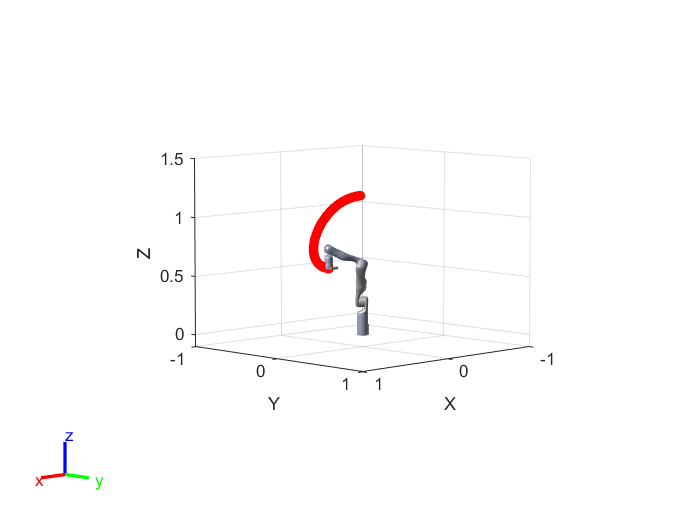

% Return to initial configuration
figure;
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20)
    drawnow;
end

**Question**: Comment on the difference between Joint-space control and task-space control. Where does the difference come from? 

## For the original guideline, please checkout:

[https://www.mathworks.com/help/robotics/examples/plan-and-execute-trajectory-kinova-gen3.html](https://www.mathworks.com/help/robotics/examples/plan-and-execute-trajectory-kinova-gen3.html)